# 1.2.08. Построение графиков

**Практическое занятие**

Необходимо визуализировать экспериментальный сигнал.

## Загрузка данных

В файле data.mat лежит записанный в ходе лабораторной работы сигнал `S`. Хранится он в виде таблицы из двух столбцов - `Time` и `Signal`. 

Загрузите сигнал `S` из файла **data**`.mat`

load data S

## Создание осей

Создайте новую фигуру (подсказка: `figure`)

figure

Создайте в фигуре пару осей. Переменным `a1`, `a2` присвойте указатели на эти оси (подсказка: `subplot(...,...,...)`,` =`)

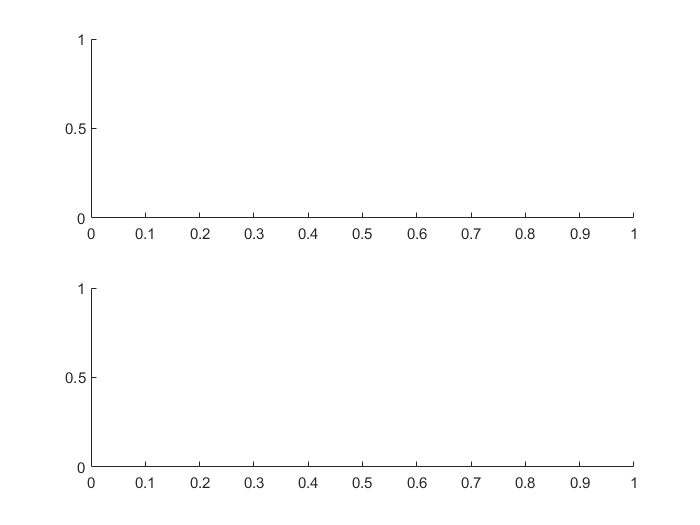

a1 = subplot(2, 1, 1);
a2 = subplot(2, 1, 2);

## Построение графика 1

В осях `a1` постройте загруженный сигнал от времени как обычную линию. При построении передайте переменной `h` указатель на график (подсказка: `plot()`, =)

h1 = plot(a1, S.Time, S.Signal);

Включите сетку по обеим осям (подсказка: `grid(...,...)`)

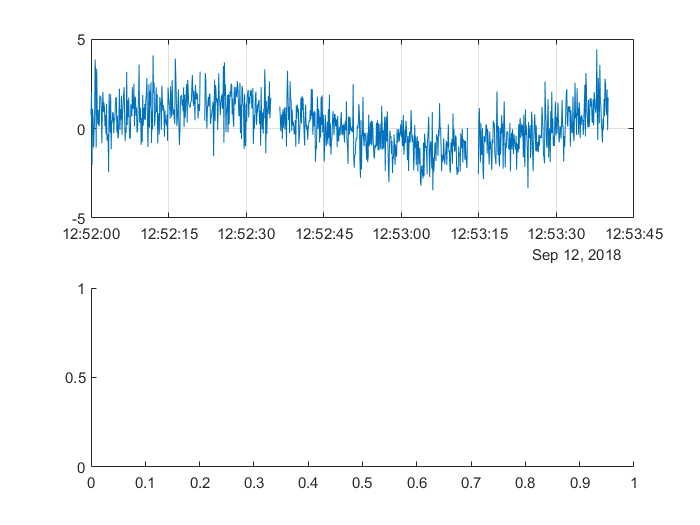

grid(a1, 'on')

## Настройка графика 1

Настройте осям `a1` пределы по оси абсцисс в соответствии со значениями столбца `Time`, чтобы в правой части графика не было пустого пространства (подсказка: `xlim(...,...)`)

xlim(a1, S.Time([1 end]))

Добавьте осям `a1` заголовок графика: **Сигнал** (подсказка: `title(...,...)`)

title(a1, 'Сигнал')

Установите толщину линии: **2** (подсказка: `LineWidth`)

h1.LineWidth = 2;

Добавьте в оси `a1` горизонтальные линии **красного** цвета через **максимум** и **минимум** сигнала (подсказка: `yline(...,...)`)

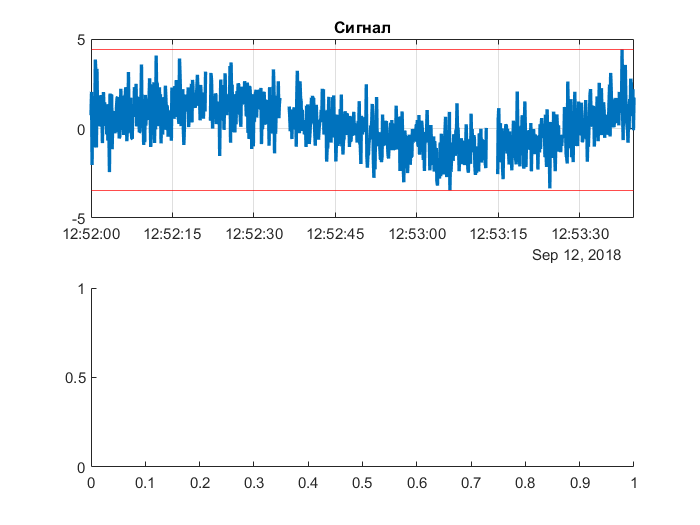

yline(a1, max(S.Signal), 'r');
yline(a1, min(S.Signal), 'r');

## Построение графика 2

В осях `a2` постройте гистограмму сигнала. При построении передайте переменной `h2` указатель на график. Гистограмма должна содержать **15** столбиков (подсказка: histogram`()`, =)

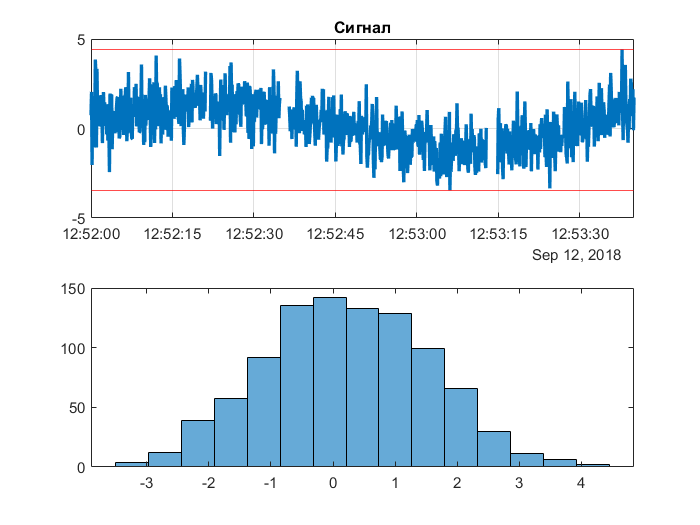

h2 = histogram(a2, S.Signal, 15);

## Настройка графика 2

Добавьте осям `a2` заголовок графика: **Распределение** (подсказка: `title(...,...)`)

title(a2, 'Распределение')

В переменную `dev` запишите стандартное отклонение сигнала. При вычислении исключите пропущенные значения (подсказка: `std(...,'omitnan')`)

dev = std(S.Signal, 'omitnan');

Переведите переменную dev в текст и добавьте слева: '**std = '** (подсказка: `num2str()`)

dev = "std = " + num2str(dev);

Отобразите значение текстовой переменной `dev` на графике в осях `a2` (подсказка: `text(...,-3,110,...)`)

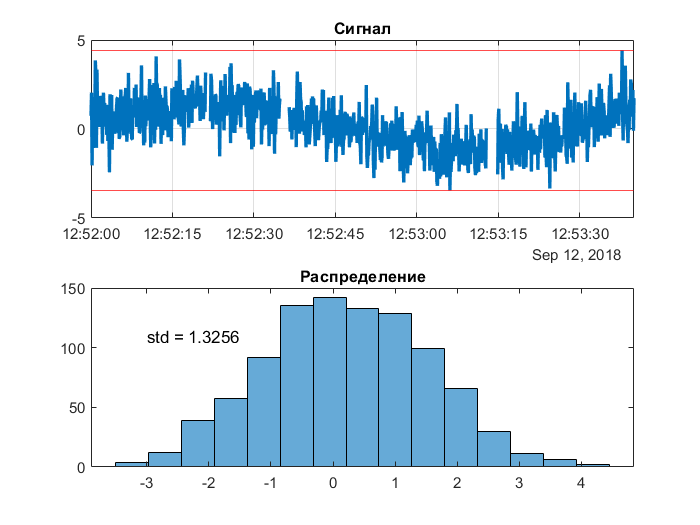

text(a2, -3, 110, dev)

*2018 © ЦИТМ Экспонента*